%{
ES115 - Class-Project Module: Drug Concentration in the Body
Author: Matthew Chietro
Version: 1.0
Date: 2026-05-01

Purpose:
    - Simulate drug concentration dynamics over time.
    - Model absorption and elimination using first-order kinetics.
    - Analyze effects of repeated dosing and accumulation.
    - Observe peak concentration and steady-state behavior.

Input:
    - Time vector and simulation duration
    - Initial concentration (IV case)
    - Drug dose amount
    - Elimination rate constant (k)
    - Absorption rate constant (ka)
    - Volume of distribution (V)
    - Dosing interval (tau)
    - Number of doses

Output:
    - Concentration vs time plots (single dose, oral model, multiple dosing)
    - Peak concentration and time-to-peak annotations
    - Therapeutic and toxic threshold markers
    - Visualization of accumulation and steady-state behavior

Engineering Algorithms:
    - Define time vector
    - Compute exponential decay for IV model
    - Use analytical solution for oral absorption/elimination model
    - Implement superposition for repeated dosing:
        * Shift time for each dose
        * Sum individual dose contributions
    - Identify peak concentration and corresponding time
    - Apply threshold visualization (therapeutic/toxic levels)
    - Plot and annotate all results

MATLAB tools/functions:
    - exp()
    - plot, yline, xline
    - text, annotation
    - for loop
    - logical indexing
    - user-defined function
    - figure
%}


clear; clc; close all;   % clear workspace, command window, and close figures



% Time Definition
t = 0:0.1:48;            % create time vector from 0 to 48 hours in 0.1 hr steps

%Parameters
C0 = 50;                 % initial concentration for IV dose (mg/L)
k  = 0.2;                % elimination rate constant (1/hr)
ka = 1.0;                % absorption rate constant (1/hr)
V  = 10;                 % volume of distribution (L)
D  = 500;                % drug dose (mg)

tau = 8;                 % dosing interval (hours)
num_doses = 6;           % total number of doses given

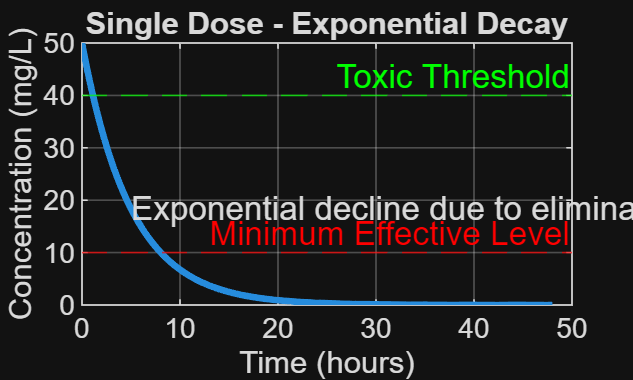

%Single Dose Decay
C_decay = C0 * exp(-k * t);   % compute exponential decay using first-order kinetics

figure;                       % open a new figure window
plot(t, C_decay, 'LineWidth', 2);  % plot concentration vs time
xlabel('Time (hours)');       % label x-axis
ylabel('Concentration (mg/L)'); % label y-axis
title('Single Dose - Exponential Decay'); % plot title
grid on;                      % turn on grid for readability

% Add annotation explaining curve behavior
text(5, C_decay(find(t>=5,1)), ...
    'Exponential decline due to elimination', ...
    'FontSize',10);           % place explanatory text on graph

yline(10, '--r', 'Minimum Effective Level'); % draw horizontal line for therapeutic minimum
yline(40, '--g', 'Toxic Threshold');         % draw horizontal line for toxic level

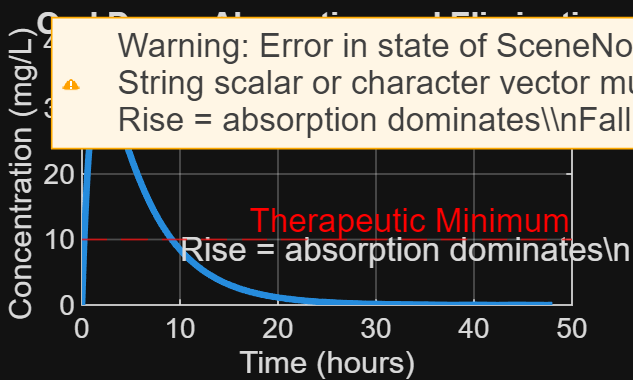

%Oral Dose Model
C_oral = drug_concentration(t, D, k, ka, V); % call user function to compute oral concentration

figure;                       % create new figure
plot(t, C_oral, 'LineWidth', 2); % plot oral concentration curve
xlabel('Time (hours)');       % label x-axis
ylabel('Concentration (mg/L)'); % label y-axis
title('Oral Dose - Absorption and Elimination'); % title
grid on;                      % enable grid

% Find peak concentration and time
[Cmax, idx] = max(C_oral);    % find maximum concentration and index
tmax = t(idx);                % get time corresponding to peak

hold on;                      % keep plot active for additional elements
plot(tmax, Cmax, 'ro', 'MarkerFaceColor','r'); % mark peak with red dot

% Annotate peak point
text(tmax, Cmax, ...
    sprintf('  Peak\nCmax=%.2f\nt=%.2f hr', Cmax, tmax)); % display peak info

% Explain phases of curve
text(10, C_oral(find(t>=10,1)), ...
    'Rise = absorption dominates\nFall = elimination dominates');

yline(10, '--r', 'Therapeutic Minimum'); % minimum effective concentration
yline(40, '--g', 'Toxic Limit');         % toxic concentration threshold

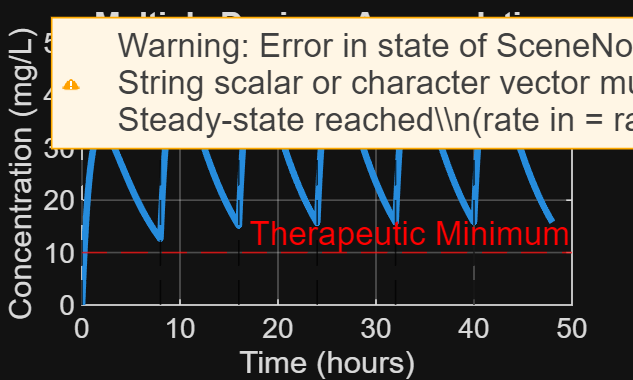


% Multiple Dosing Model
C_total = zeros(size(t));    % initialize total concentration array with zeros

for n = 0:num_doses-1        % loop through each dose
    t_shift = t - n*tau;     % shift time to simulate delayed dosing
    
    dose = drug_concentration(t_shift, D, k, ka, V); % compute contribution of this dose
    
    dose(t_shift < 0) = 0;   % remove values before dose was administered
    
    C_total = C_total + dose; % add this dose's contribution to total concentration
end

figure;                       % open new figure
plot(t, C_total, 'LineWidth', 2); % plot accumulated concentration
xlabel('Time (hours)');       % x-axis label
ylabel('Concentration (mg/L)'); % y-axis label
title('Multiple Dosing - Accumulation'); % title
grid on;                      % enable grid

hold on;                      % keep plot active

% Mark each dosing time with vertical lines
for n = 0:num_doses-1
    xline(n*tau, '--k', 'Dose'); % vertical dashed line at each dose time
end

% Annotate steady-state behavior
text(30, max(C_total)*0.8, ...
    'Steady-state reached\n(rate in = rate out)', ...
    'FontSize',10);

yline(10, '--r', 'Therapeutic Minimum'); % therapeutic lower bound
yline(40, '--g', 'Toxic Limit');         % toxic upper bound

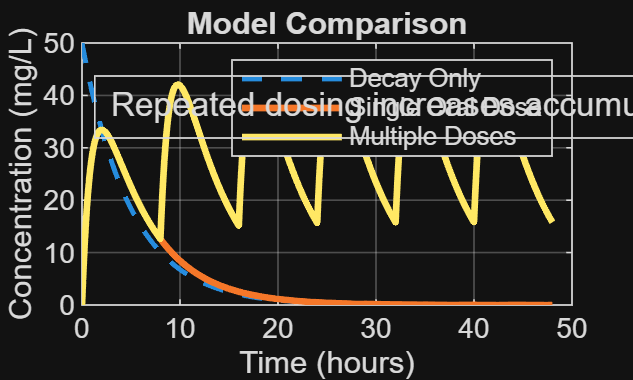

%Comparison Plot
figure;                                   % create new figure
plot(t, C_decay, '--', 'LineWidth', 1.5); hold on; % plot decay (dashed)
plot(t, C_oral, 'LineWidth', 2);           % plot oral model
plot(t, C_total, 'LineWidth', 2);          % plot multiple dosing

legend('Decay Only','Single Oral Dose','Multiple Doses'); % legend
xlabel('Time (hours)');                   % x-axis label
ylabel('Concentration (mg/L)');           % y-axis label
title('Model Comparison');                % title
grid on;                                  % grid

% Add general annotation box
annotation('textbox',[0.15 0.7 0.3 0.1],...
    'String','Repeated dosing increases accumulation',...
    'FitBoxToText','on');


% Clinical Interpretation

disp('--- Clinical Interpretation ---');  % print header to command window

--- Clinical Interpretation ---


disp(['Peak concentration: ', num2str(Cmax)]); % display peak concentration

Peak concentration: 33.4365


disp(['Time to peak: ', num2str(tmax), ' hr']); % display time of peak

Time to peak: 2 hr


disp('Short intervals -> accumulation risk');   % explain dosing risk

Short intervals -> accumulation risk


disp('Long intervals -> sub-therapeutic levels'); % explain underdosing

Long intervals -> sub-therapeutic levels


disp('Steady-state reached after ~4–5 half-lives'); % pharmacokinetic insight

Steady-state reached after ~4–5 half-lives


% User Defined Function
function C = drug_concentration(t, D, k, ka, V)
% Computes drug concentration for oral dosing model

C = (D * ka ./ (V * (ka - k))) .* ... % scaling factor based on pharmacokinetics
    (exp(-k .* t) - exp(-ka .* t));   % difference of exponentials (elim - absorption)

end
